## Assignment 4

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

% Class Objects
OM = OrbitManeuver;
warning('off','all')

## Task 1: Special Maneuver: Phasing

Below we calculate the total detla_v for a phasing maneuver from inclined LEO orbit to GEO using a phasing orbit to time the interception, 

first only with in inclination burn when intercepting the target and in the second subtask, we split the inclination burn before and after the transfer

% Constants and definition of LEO and GEO orbit
mu_earth          = 398600.440;            % km³/s²
Re_earth          = 6371;                  % km
% Interceptor LEO
h_leo       = 200;                   % km
a_leo       = h_leo + Re_earth;            % km
i_leo       = deg2rad(22.5);         % rad
RAAN_leo    = deg2rad(40);           % rad
u_t0        = deg2rad(17);           % rad

% Target GEO
h_geo       = 35786;                 % km
a_geo       = Re_earth + h_geo;            % km
lambda_t0   = deg2rad(200);          % rad


### Task 1a)

% Solve
[delta_v_phase, delta_v_trans1, delta_v_trans2, t_total] = ...
    OM.perform_noncoplanar_phasing_circular_orbits(a_leo, i_leo, RAAN_leo, a_geo, 0, lambda_t0, u_t0, mu_earth, 0, false);

delta_v_total = delta_v_phase + delta_v_trans1 + delta_v_trans2;

% Results of the Earth-Venus Transfer
disp("Total delta_v and transfer time");

Total delta_v and transfer time


delta_v_total   % km / s

delta_v_total = 4.1689

t_total      % s

t_total = 4.7857e+04

### Task 1b)

% Solve
[delta_v_phase, delta_v_trans1, delta_v_trans2] = ...
    OM.perform_noncoplanar_phasing_circular_orbits(a_leo, i_leo, RAAN_leo, a_geo, 0, lambda_t0, u_t0, mu_earth, 0,true);

delta_v_total2 = delta_v_phase + delta_v_trans1 + delta_v_trans2;

delta_v_phase

delta_v_phase = 2.2410

delta_v_trans1

delta_v_trans1 = 2.4646

delta_v_trans2

delta_v_trans2 = 1.6884

disp(['Total deltaV for two-burn minimum inclination change at GEO: ', num2str(delta_v_total2), ' km/s']);   

Total deltaV for two-burn minimum inclination change at GEO: 6.394 km/s


## Task 2: High-thrust maneuver using optimization

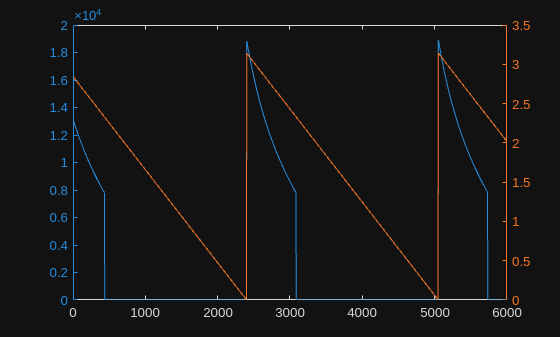

% Determine relevant parameters for transfer orbit (Hohmann Transfer)
r_initial = a_leo;
r_target = a_geo;

% Calculate angular velocity for initial and target orbit
omega_initial = sqrt(mu_earth / r_initial^3);
omega_target = sqrt(mu_earth / r_target^3);

% Angle to node for interceptor
nu = @(t_w) pi - mod(u_t0 + omega_initial * t_w, pi);

x = linspace(1, 6.0E3, 1000);

t_trans = zeros(size(x));  % preallocate
nu_all = zeros(size(x));

for k = 1:length(x)

    [~, ~, ~, ~,~,t_trans(k)] = OM.one_tangent_burn_LEO_GEO(a_leo, a_geo, nu(x(k)), mu_earth);
    nu_all(k) = nu(x(k));

end

figure
yyaxis left
plot(x, t_trans)
yyaxis right
plot(x, nu_all)

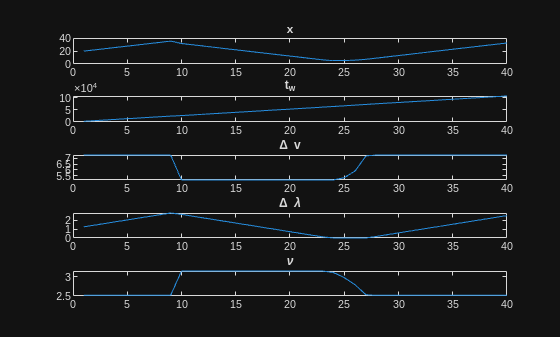


[x_all, t_w_all, delta_v_all, delta_lambda_all, nu_opt_all] = OM.perform_two_impulse_transfer(a_leo, i_leo, RAAN_leo, a_geo, 0, lambda_t0, u_t0, mu_earth, 40);


figure
subplot(5,1,1), plot(x_all), title('x')
subplot(5,1,2), plot(t_w_all), title('t_w')
subplot(5,1,3), plot(delta_v_all), title('\Delta v')
subplot(5,1,4), plot(delta_lambda_all), title('\Delta \lambda')
subplot(5,1,5), plot(nu_opt_all), title('\nu')